# Input and Outputs - Part 1: Solutions        

   Do I have to have MATLAB installed on my computer right now? No, you can use  [MATLAB Online](https://matlab.mathworks.com/)!

## **What we covered last week**

Last week we learnt about,

- Loop structures can be used to automate the process of repeating an instruction.

- There are two kinds of loop structures: For loops and While loops. 

- For loops can be used when the number of iterations is known and While loops can be used when the number of iterations is not known.

- Vectorization can be used to replace loops where each element in an object (i.e array) is treated as a whole object. 

- Conditional statements can be used to execute specific parts of an algorithm

## Introduction

Input and Output in programming can be understood as the communication between a computer programme and its user. The **Input i**s seen as a user providing input/data into a programme and the** Output** is understood as outputting/returning some form of processed data to the user**. ** In MATLAB, the command window can be used to execute commands on inputs which is usually some form data. The MATLAB Workspace keeps track of all variables and hence the inputs and outputs from various code executions on MATLAB. This lesson will be split into two parts: part a and part b. In part a we go over the different input/output systems in MATLAB and touch on reading and writing file contents. 

Consider an example of displaying the term "Hello World!" in the command window, using the built-in MATLAB function [disp](https://www.mathworks.com/help/matlab/ref/disp.html)() the input would be "Hello World!" and the output would be a text displaying the phrase. This is the simplest idea of an input output relationship in programming.

input = "Hello World!";
disp(input)

There are several input/output methods in MATLAB. There are 4 methods for input:

- MATLAB Command window

- Operating system command line

- Graphical User Interface (Apps)

- Writing and retrieving data from files

There are 2 main ways of data output:

- Writing to the terminal window and,

- Writing to a file.

We will demonstrate these in this Live Script.

### MATLAB Command Window

Using the built-in [input](https://www.mathworks.com/help/matlab/ref/input.html)*()* function, we can read in data. An example  of this approach is outlined in the pseudo-code below:

Copy and paste this code in to the Command Window below and comment on the outcome of the results in the line below by stating what your input is and what your output is. 

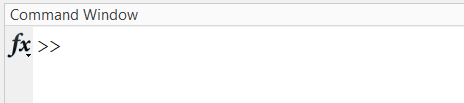

### Operating system command line

MATLAB is able to be access commands through the command line interface of the operating system where MATLAB is installed. This method is often popular in unix-like environments where users are accustomed to using the Bash command line. However in this lesson we will not be going into much detail. For further reference, please follow this [link](https://www.cdslab.org/matlab/notes/data-transfer/io/index.html#inputoutput-data-from-a-graphical-user-interface).

### Graphical User Interface (Apps)

With MATLAB you can use built-in short apps or build quick applications using either [MATLAB App Designer](https://www.mathworks.com/products/matlab/app-designer.html) or [Live Tasks](https://www.mathworks.com/help/matlab/develop-live-editor-tasks.html?s_tid=blogs_rc_4). Graphical interfaces provide a very convenient way for user to input data. A common built-in function is [inputdlg](https://www.mathworks.com/help/matlab/ref/inputdlg.html)*()*, which creates a dialog box that takes user inputs. For more information see this [link](https://www.mathworks.com/help/matlab/ref/inputdlg.html).

### Writing and Retrieving Data from Files

As you progress with programming, you will realize that inputs are most commonly fed into a particular  programming environment  through data sources such as excel files and databases. When we start working with large datasets, using the command-line is no longer efficient. Therefore, we start using methods to read and write data from a file where the path if often specified to a specific folder. There are several built-in function, but we will only be looking at a select few. These include:

- [load](https://www.mathworks.com/help/matlab/ref/load.html)() - Load MATLAB variables from file into MATLAB.

- [save](https://www.mathworks.com/help/matlab/ref/save.html)() - save MATLAB variables from MATLAN workspace  into a MATLAB '.mat' file.

- [fscanf](https://www.mathworks.com/help/matlab/ref/fscanf.html)() - Read data from text file.

- [fprintf](https://www.mathworks.com/help/matlab/ref/fprintf.html)() - Write data to a text file.

- [readtable](https://www.mathworks.com/help/matlab/ref/readtable.html)() - create from Excel Spreadsheet or comma-separated value (CSV) file.

- [writetable](https://www.mathworks.com/help/matlab/ref/writetable.html)() - Write to an Excel spreadsheet or CSV file.

- [imread](https://www.mathworks.com/help/matlab/ref/imread.html)() - Read image from graphics  file.

- [imwrite](https://www.mathworks.com/help/matlab/ref/imwrite.html)() - Write image to graphics file.

Typically in programming, an algorithm is built based on a particular dataset. This data can  take the form of  data types such as a [structure](https://www.mathworks.com/help/matlab/ref/struct.html), excel file or image. This data can be loaded into MATLAB in a multitude of ways. Below is a simple example of how variables can be assigned, viewed on the MATLAB workspace and saved into a file.

#### Loading and Saving MATLAB workspace variables

Variables that are on the MATLAB workspace can be saved to a specified format file. Below is a simple example of how variables can be assigned, viewed on the MATLAB workspace and saved into a specified file.

% Sample of variables to create in the MATLAB workspace
a = 1; 
b = 2; 
c = 3; 
d = 4; 
p = rand(1, 10);

- Save all the  variables on the workspace

- Save selected variables on the workspace

- Save variables with a specified format (in this example we will specify  a .txt file format.)

Similarly, we can reload the same files into the MATLAB workspace if needed, using the [load](https://www.mathworks.com/help/matlab/ref/load.html)() function. Look at the variables now in the workspace. We start by clearing any variables on the workspace to see the effect of the load() functionality. Note: Tying "[clear](https://www.mathworks.com/help/matlab/ref/clear.html#:~:text=To%20clear%20all%20variables%20from,or%20script%2C%20use%20clear%20functionName%20.)" in the MATLAB command window will clear all variables in the current workspace.

clear

Using the load function, all the previously saved variables can now be loaded onto the workspace.

Note: A .mat file extension is a MATLAB specific file extension. 

load("allVariables.mat");
load("onlySelectVariables.mat");
load("withFormat.txt");

Now you try! Create variables and assign numbers to them and save them to a .txt file called "testVariables.txt". 

### Reading and writing formatted file using fscanf()

As seen in the previous section, load() is one way of loading the contents of a saved file onto the MATLAB environment. Other data reading functionality is the [fscanf](https://www.mathworks.com/help/matlab/ref/fscanf.html)() function  which will read in the contents of text file. The contents from this file can be stored as a variable and accessed from the MATLAB environment. 

fileID = fopen('data.txt', 'r');
formatSpec = '%f';
A = fscanf(fileID, formatSpec)
fclose(fileID);

Unlike the C language’s `fscanf()`, in MATLAB `fscanf()` is vectorized meaning that it can read multiple lines all at once. Here, the attribute `'r'` states that the file is opened to read it (vs "w" for writing, or some other purpose). Look at the [documentation](https://www.mathworks.com/help/matlab/) for fscanf() to see how the other attributes that can be used. 

fileID = fopen('temperature.dat', 'r'); 
degrees = char(176); 
[A, ~] = fscanf(fileID, ['%d' degrees 'C']) 
fclose(fileID); 

The fscanf method of reading the contents of a file is very powerful but rather detailed, low-level and cumbersome, especially when you have to define the format for the content of the file appropriately. Most often, other higher-level MATLAB’s built-in function come to rescue us from the hassles of using `fscanf()`.

Now you try! Create a text file on you local machine with the statement  "Hello World!". Save this file locally and load the text file using the fscanf() function. Comment on the results in the line below.

## **Part 1 Summary**

In part a of Inputs and Outputs we learnt,

- Different Input and Output systems 

- Importing data from various structured data types

***Copyright 2022 The MathWorks, Inc. & Opti-Num Solutions (Pty) Ltd.***